for a harmonic oscillator


$$\frac{\textrm{dx}}{\textrm{dt}}=\textrm{dp},\frac{\textrm{dp}}{\textrm{dt}}=-\textrm{kx}$$


$\hat{\;H\;}$=$-$

% 点数
N = 2000;
% x的范围;
x= linspace(-1,1,N);
% x的初始值;
x_0 = -0.5;

% 常数
C = 1;
a = 2e-3;
k = 400;

% 位移和时间步长
dx = 1e-3;
dt = 5*1e-7;

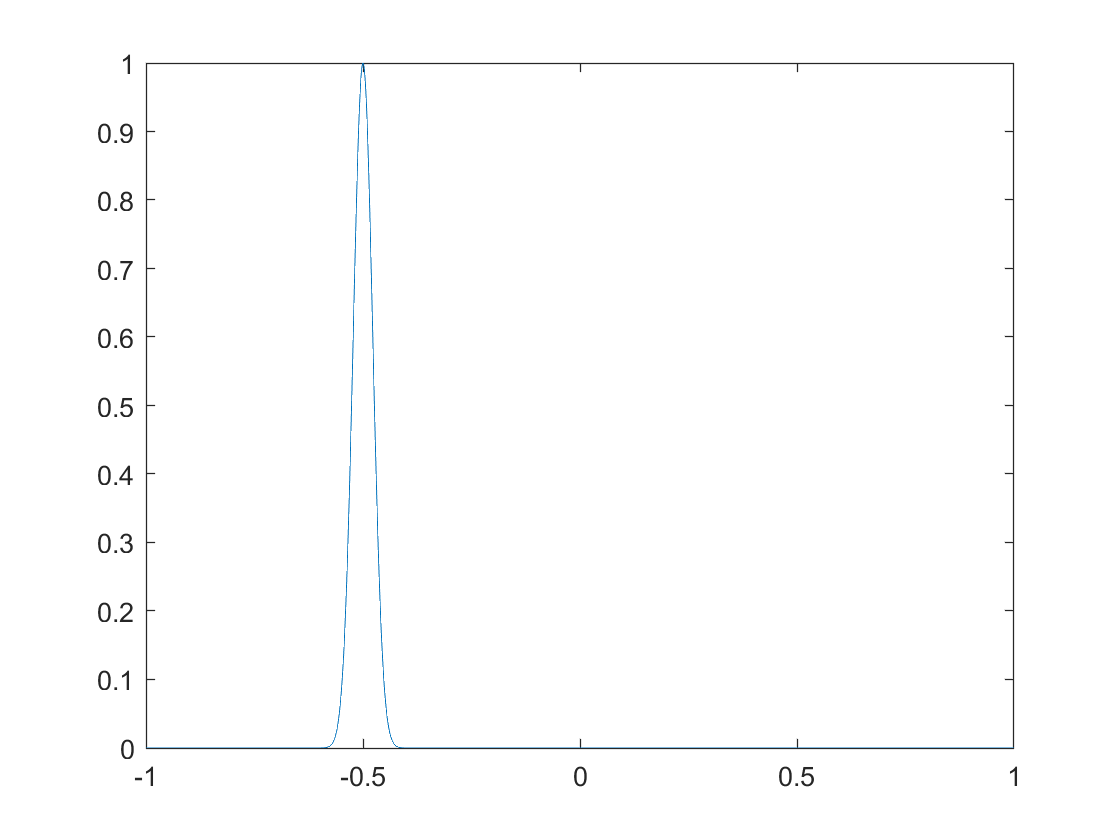

psi0 = C*exp(-(x-x_0).^2/a).*exp(1i*k*x);
plot(x,real(psi0).^2+imag(psi0).^2)

% 提取虚部和实部
R_0 = real(psi0);
I_0 = imag(psi0);
I_next = zeros(1,N);
R_next = zeros(1,N);


% 创建谐振子势
% V = zeros(1, N);
% V(1:1000) = 0;
% V(1000:N) = 8e4;
V = 0.5*x.^2

V =     0.5000    0.4990    0.4980    0.4970    0.4960    0.4950    0.4940    0.4930    0.4920    0.4910    0.4900    0.4891    0.4881    0.4871    0.4861    0.4851    0.4841    0.4831    0.4822    0.4812    0.4802    0.4792    0.4782    0.4773    0.4763    0.4753    0.4743    0.4734    0.4724    0.4714    0.4704    0.4695    0.4685    0.4675    0.4666    0.4656    0.4646    0.4637    0.4627    0.4617    0.4608    0.4598    0.4589    0.4579    0.4569    0.4560    0.4550    0.4541    0.4531    0.4522


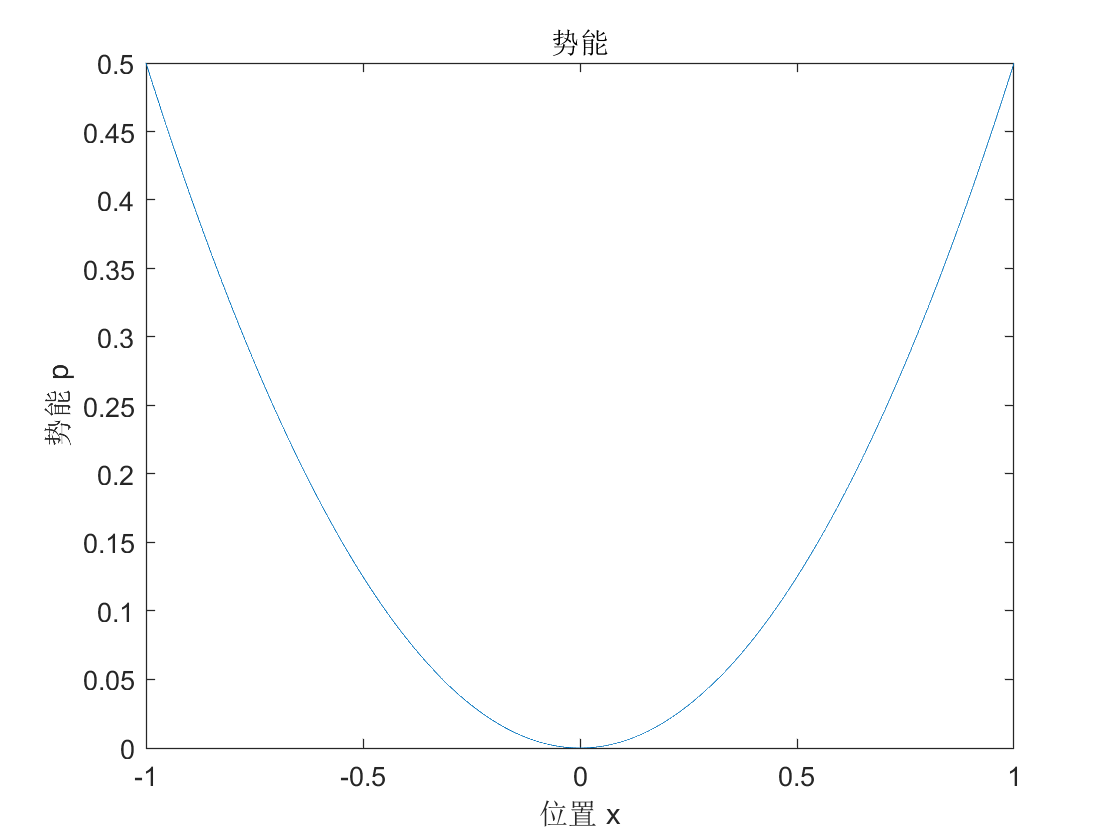


% 画出V的图像
plot(x,V)
title('势能');
xlabel('位置 x');
ylabel('势能 p');

pause(2)



% 初始化当前的实部和虚部
I_now = I_0;
R_now = R_0;


psi=[]


psi =

     []



psi_r = [];
psi_i = [];
for i = 1:N
    [t,psii] = ode45(@fun,0:5e-3:200*5e-3,[R_0(i) 0 I_0(i) 0]);
    psi_r = [psi_r;psii(:,1)'];
    psi_i = [psi_i;psii(:,3)'];
end
size(psi_r)

ans =         2000         201


psi_r(:,1)

ans =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


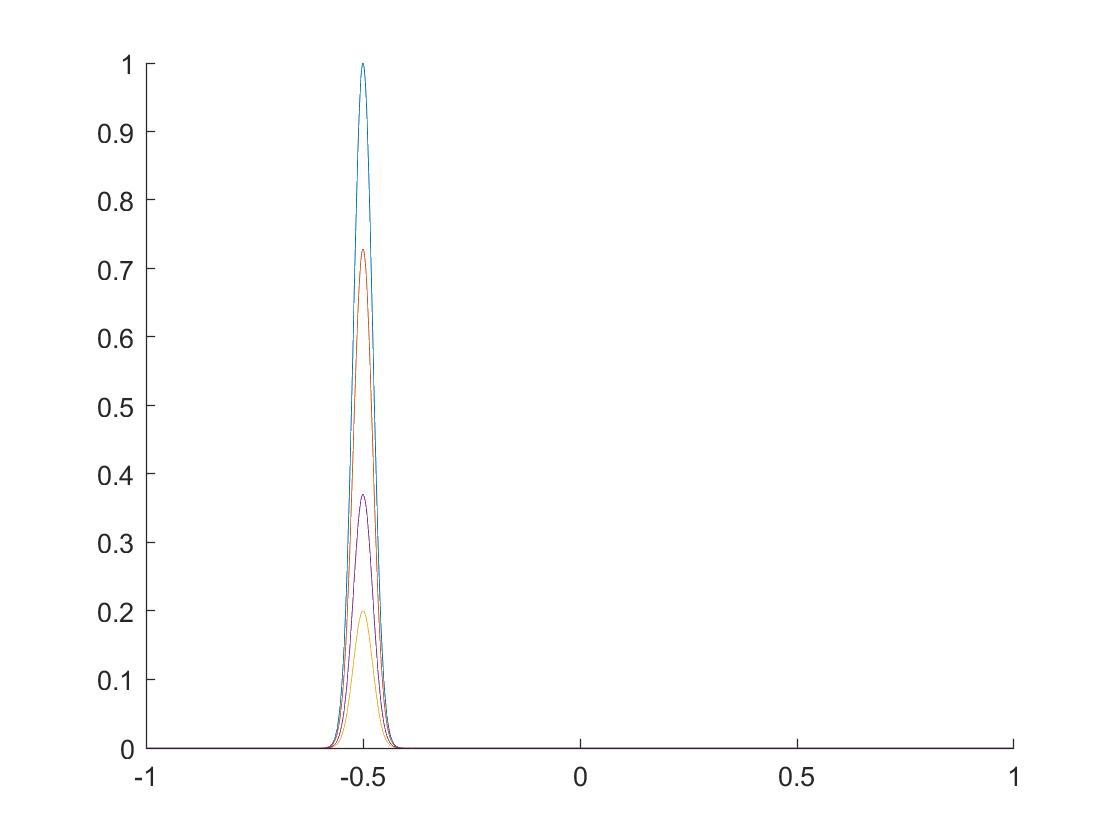

figure;

hold on
plot(x',psi_r(:,1).^2+psi_i(:,1).^2)
plot(x',psi_r(:,50).^2+psi_i(:,50).^2)
plot(x',psi_r(:,100).^2+psi_i(:,100).^2)
plot(x',psi_r(:,200).^2+psi_i(:,200).^2)
hold off

function dy = fun(t,y)
    dy = zeros(4,1);
    dy(1) = y(2);
    dy(2) = -5.*y(1);
    dy(3) = y(4);
    dy(4) = -5.*y(3);
end
